x0 = zeros(size(weigth)) + 1;

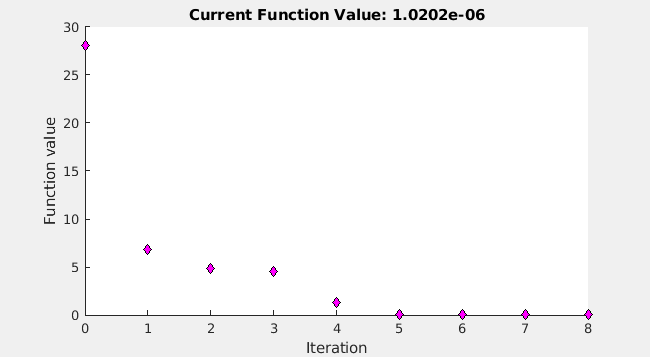


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


% Pass fixed parameters to objfun
objfun3 = @(x)objectiveFcn(x,weigth);

% Set nondefault solver options
options3 = optimoptions("fmincon","PlotFcn","optimplotfval");

% Solve
[solution,objectiveValue] = fmincon(objfun3,x0,[],[],[],[],zeros(size(x0)),...
    ones(size(x0)),[],options3);


% Clear variables
clearvars objfun3 options3

solution
objectiveValue

View the nonlinear constraint function values at the solution.

[ccons,ceqcons] = constraintFcn(solution)

function f = objectiveFcn(x,weigth)
f = sum(x .* weigth);
end

function [c] = constraintFcn(x)
end